%
%   Francesco Peluso - @francescopeluso
%
%   Data Science 25-26 course
%   Computer Engineering, Master's Degree
%   Dept. of Information and Electrical Engineering and Applied Mathematics
%

clear all, close all, clc;

%% Exercise on MMSE estimator


% We're going to see...
%  a. how to implement the MMSE estimator for the assigned model
%  b. how to understand the relative importance of the prior information
%     and of the observed data in a Bayesian estimation problem
%  c. how to perform a comparison between MMSE and ML estimation
%  d. the role of the available amount of data when comparing two etimation
%     approaches


%% Point a.
% Write a snippet of code that generates N data samples for the model:
%   X_n = Y + W_n
% where Y is the quantity we want to estimate, and it is distributed as a
% zero mean Gaussian random variable with variance equal to sigma2_prior.
% W_i is a iid Gaussian noise with zero eman and variance equal to sigma2.
% X = generate_data_rand_y(N, sigma2_prior, sigma2).

% Also, implement a Montecarlo simulation for the MSE.

N = 250

N = 250

mu_Y = 0

mu_Y = 0

sigma2_prior = 1;
sigma2 = 0.3;

function [X, Y_true] = generate_data_rand_y(N, sigma2_prior, sigma2)
    Y_true = randn * sqrt(sigma2_prior);   % vero Y
    % rumore - vettore colonna di dimensione N, con valori gaussiani standard
    % Moltiplicando per la radice si scala la varianza da 1 (generata
    % automaticamente da randn) a sqrt(sigma2)
    W = randn(N, 1) * sqrt(sigma2);        
    X = Y_true + W;                        % dati osservati
end


X = generate_data_rand_y(N, sigma2_prior, sigma2)

X =     1.5421
   -0.6996
    1.0099
    0.7123
   -0.1786
    0.3002
    0.7253
    2.4976
    2.0546
   -0.2017
    2.2000
    0.9350
    0.5031
    0.9291
    0.4254


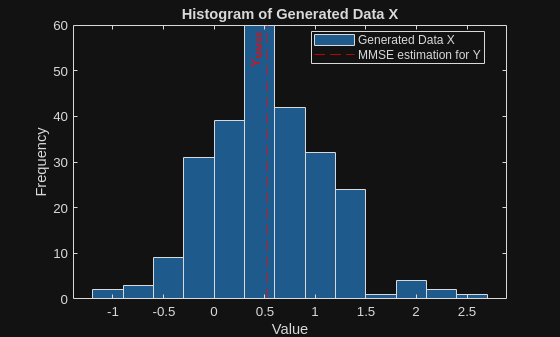


% An MMSE estimator is defined as g* = argmin[g](E[g(X)-Y])
% which is E[Y|X=x], so...
Y_MMSE = (mean(X) * sigma2_prior) / (sigma2_prior + (sigma2 / N));

figure;
set(gca, 'TickLabelInterpreter', 'latex');
histogram(X);
xlabel('Value');
ylabel('Frequency');
title('Histogram of Generated Data X');

% Plot the MMSE estimate
xline(Y_MMSE, 'r--', 'Y_{MMSE}', 'LabelHorizontalAlignment', 'left');
legend('Generated Data X', 'MMSE estimation for Y', 'Location', 'best');


% Theoretical posterior variance (MSE)
S2_theoretical = (sigma2_prior * (sigma2 / N)) / (sigma2_prior + (sigma2 / N))

S2_theoretical = 0.0012

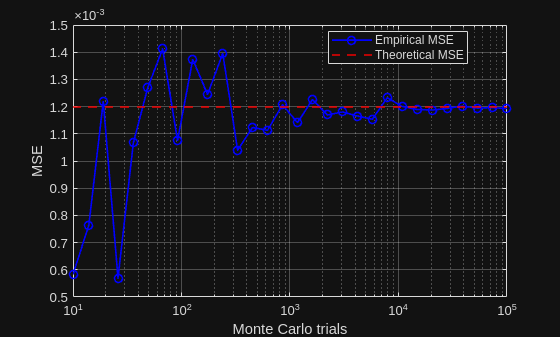


N_MC = round(logspace(1, 5, 30));
MMSE_mse = zeros(length(N_MC), 1);

for i = 1:length(N_MC)
    n_trials = N_MC(i);

    mse_sum = 0;

    for k = 1:n_trials
        [X, Y_true] = generate_data_rand_y(N, sigma2_prior, sigma2);
        Y_hat = (mean(X) * sigma2_prior) / (sigma2_prior + (sigma2 / N));
        mse_sum = mse_sum + (Y_hat - Y_true)^2;   % errore corretto
    end
    
    MMSE_mse(i) = mse_sum / n_trials;
end

figure;
semilogx(N_MC, MMSE_mse, 'b-o', 'LineWidth', 1.2); hold on;
yline(S2_theoretical, 'r--', 'LineWidth', 1.5);
xlabel('Monte Carlo trials');
ylabel('MSE');
legend('Empirical MSE', 'Theoretical MSE', 'Location', 'best');
grid on;



%% Point b.
% Plot the posterior distribution of the unknown parameter for different
% values fo the variances sigma2_prior and sigma2. Given the shape of the
% distribution, comment on the relative importance of the priori
% information and of the observed data.



%% Point c.
% Compute the MSE of the MMSE and ML estimator for different values of the
% variance sigma2_prior. Motivate why one of the approaches perform better
% than the other when varying sigma2_prior.

sigma2_prior_values = [1, 2, 4, 8, 10];
sigma2_values = [0.25, 0.50, 1, 2, 4];
n_trials = 1000;  % montecarlo trials

MSE_MMSE = zeros(length(sigma2_prior_values), length(sigma2_values));
MSE_ML = zeros(length(sigma2_prior_values), length(sigma2_values));

for j = 1:length(sigma2_prior_values)
    sigma2_prior = sigma2_prior_values(j);

    for l = 1:length(sigma2_values)
        sigma2 = sigma2_values(l);
        mse_sum_mmse = 0;
        mse_sum_ml = 0;

        for k = 1:n_trials
            [X, Y_true] = generate_data_rand_y(N, sigma2_prior, sigma2);
            
            % ML estimator
            Y_hat_ml = mean(X);
            mse_sum_ml = mse_sum_ml + (Y_hat_ml - Y_true)^2;

            % MMSE estimator
            Y_hat_mmse = (mean(X) * sigma2_prior) / (sigma2_prior + (sigma2 / N));
            mse_sum_mmse = mse_sum_mmse + (Y_hat_mmse - Y_true)^2;
        end

        MSE_MMSE(j, l) = mse_sum_mmse / n_trials;
        MSE_ML(j, l) = mse_sum_ml / n_trials;
    end
end